# Sim 2 Robot Manipulator

Physical constants

R = 5; % m
g = 10; % m/s^2
b = 75; % Ns
M = 1.1; % kg
K_EaT = 25; % metric

A = [0 1; -g/R -b/(M*R^2)];
B = [0; K_EaT/(M*R^2)]

B =          0
    0.9091


C = [1 0];
K = [6 1];
x_init = 0;
r = 1; 
calibration_factor = 8;
A-B*K

ans =          0    1.0000
   -7.4545   -3.6364


out = sim('Robot_Manipulator_Simulink.slx', 6);

F_v = mean(out.y.Data(end-10:end)) % calculate final value

F_v = 0.9757

% t = out.y.Time(out.y.Data <= 0.98*F_v); % calculate times above -2% final value
t = out.y.Time(out.y.Data >= 1.02*F_v); % calculate times above -2% final value

T_s = t(end)

T_s = 2.1479

OS = (findpeaks(out.y.Data) - F_v) / F_v

OS =     0.0605
    0.0002


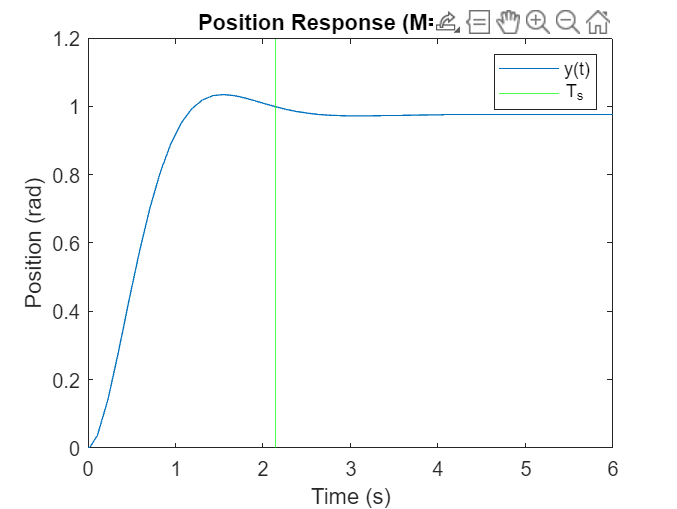


% y(t) plot
plot(out.y.Time, out.y.Data)
xline(T_s, 'g')
xlabel("Time (s)")
ylabel("Position (rad)")
title("Position Response (M=1.1kg)")
legend("y(t)", "T_s")

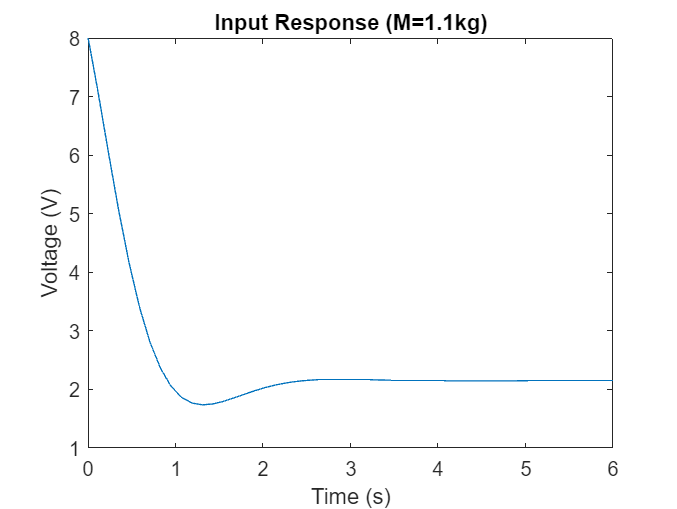


% u(t) plot
plot(out.u.Time, out.u.Data)
xlabel("Time (s)")
ylabel("Voltage (V)")
title("Input Response (M=1.1kg)")


u_final = out.u.Data(end)

u_final = 2.1464


SSE = r - F_v

SSE = 0.0243